## Initialization

clear all
clc
clf 

% Environment
Zseabed = 350;
c0 = 1500;

% Receiver Location
xr = 0;
zr = zeros(1,9);
for i = 1 : length(zr);
    zr(i) = 25*i;
end

% Signal Properties
Sigs = load('Received.mat');
n_reflect = 8;
t = 6.4;
dt = 2e-4;
step = t/dt;
t_input = linspace(0,t,step)

delay_time = 2.0000e-04

$$a = 1500\,\mathrm{tt}$$

$$b = 1500\,\mathrm{tt}+\frac{3}{10}$$

$$a = \frac{62491}{60}$$

$$a = 1041.5166666666666666666666666667$$

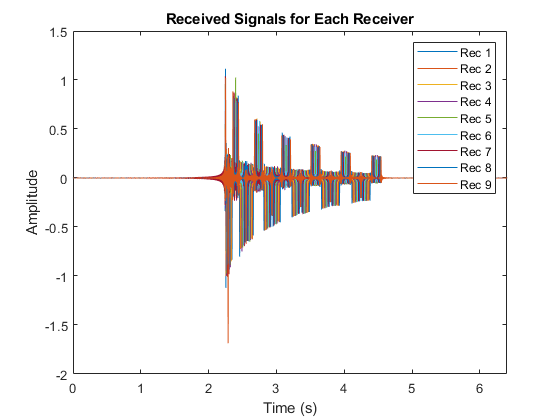


% Plot received signal from multiple receiver
for i = 1 : length(zr);
    plot(t_input, Sigs.RecSig(i,:))
    hold on
end
xlim([0 6.4])
ylim([-2 1.5])
legend('Rec 1', 'Rec 2', 'Rec 3','Rec 4','Rec 5','Rec 6','Rec 7','Rec 8', 'Rec 9')
title('Received Signals for Each Receiver')
xlabel('Time (s)')
ylabel('Amplitude')
hold off


% Rough estimation of the source location 
syms tt 
[sig1, t1] = findpeaks(Sigs.RecSig(1,:), 'MinPeakHeight',0.7);
[sig2, t2] = findpeaks(Sigs.RecSig(2,:), 'MinPeakHeight',0.7);

delay_time = abs(t2(1)-t1(1))*dt
a = c0 * tt
b = c0 *  (tt+ delay_time)
a = c0 * solve( 25^2 + a^2 -b^2 ==0,tt)
a= vpa(a)

## Inverse Source Problem

% Set the search area grid
xs = 900:5:1200;
zs = 10:5:200; % 0 begin from sea surface
plotgrid = zeros(length(zs),length(xs));

% Find the source
for i = 1:length(xs);
    for j = 1:length(zs);
        % Wave container for the grid
        Superpose_Sigs = zeros(1,length(Sigs.RecSig(1,:)));
        for k = 1:size(zr,2);
            % Inverse the Receiver Signal
            Sig_Inv = flip(Sigs.RecSig(k,:));

            % Send the inverse signal to the search area grid (Receiver
            % become source, and vice versa
            Sig_to_Src = Green_Function(Sig_Inv,xs(i),zs(j),xr,zr(k),dt,n_reflect,Zseabed,c0);

            % Superpose signals from each receiver to the container
            Superpose_Sigs = Superpose_Sigs + Sig_to_Src;
        end
        % Find the maximum energy of the superpose wave
        Max_Energy = sum(Superpose_Sigs.^2, 'all');

        % Map the maximum energy to the grid
        plotgrid(j,i) =  Max_Energy;
    end
end


## Plot The Heatmap

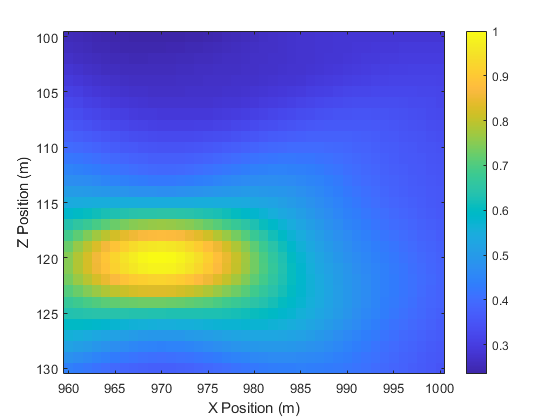

image(xs,zs,plotgrid/(max(max(plotgrid))),'CDataMapping','scaled')
hold on
colorbar
xlabel('X Position (m)')
ylabel('Z Position (m)')